%% Load experiment data
if (~exist("session2","var"))
    load("group-01.02.mat");
end

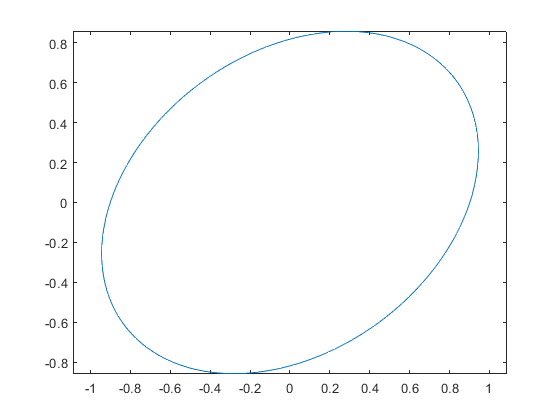

%% Calculate polarization state
f = session2.task2.frequency;
R0 = session2.task2.antennas_distance;
H = session2.task2.reflection_height(1);
epsilon1 = 8.854e-12;
epsilon2 = session2.task2.dielectric_prermittivity; epsilon2 = epsilon2 * 8.8541878128e-12;
phi = 0.2*pi; % In the setup this is pi/2
tau = 0.2*pi; % In the setup this is 0

amplitudes = polarization_state(f,R0,H,epsilon1,epsilon2,phi,tau);

plot_ellipse(amplitudes)

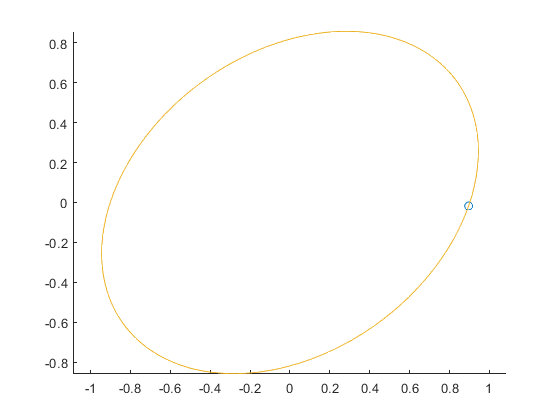

%% Animated plot
comet_ellipse(amplitudes)

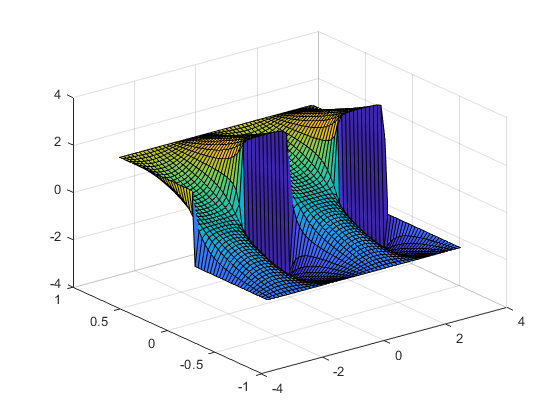

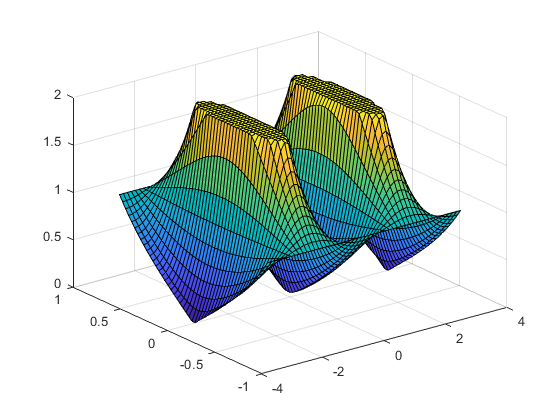

%% Make plots of our implementations
plot_phasor(50,2)

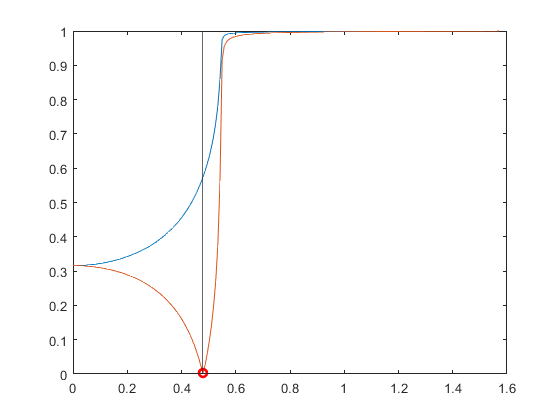

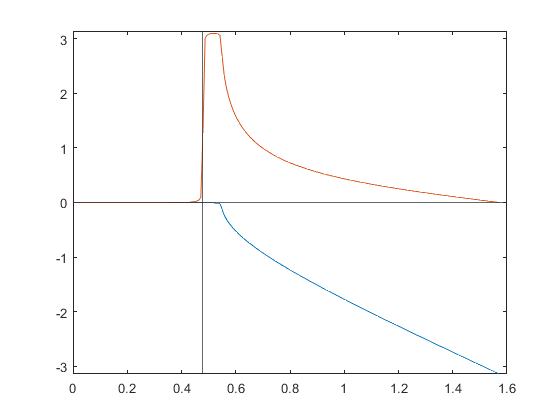

ans = 0.4791

%% Plot of the Fresnel equations vs the incident angle
plot_brewster(epsilon2,epsilon1)